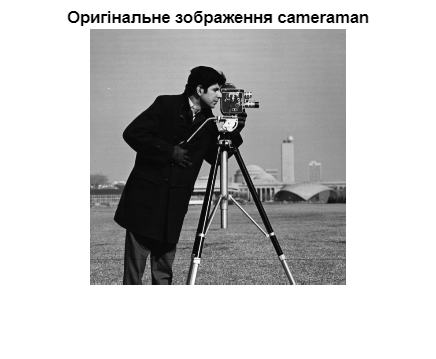

 clear, close all

% 1. Завантажив зображення з бібліотеки
a = imread('cameraman.tif');
b = imread('pout.tif');

% Відобразив вихідні зображення
figure, imshow(a), title('Оригінальне зображення cameraman');

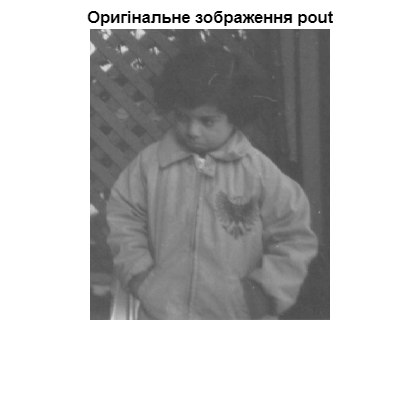

figure, imshow(b), title('Оригінальне зображення pout');

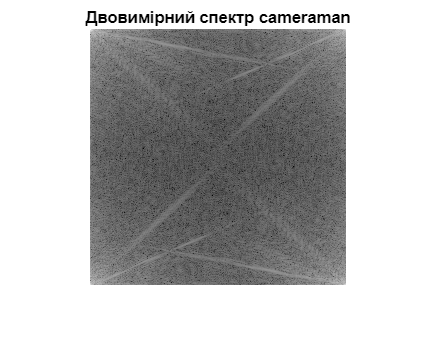

% 2. Cформував та відобразив двовимірні спектри зображень з нульовою частотою у верхньому лівому куті.
figure
F1 = fft2(a);
F2 = fft2(b);
S1 = abs(F1);
S2 = abs(F2);
S1log = log(1 + S1);
S2log = log(1 + S2);
figure, imshow(S1log, []), title('Двовимірний спектр cameraman');

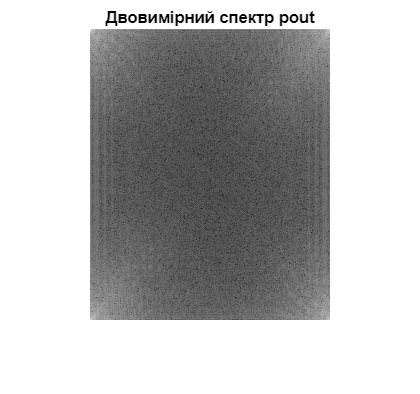

figure, imshow(S2log, []), title('Двовимірний спектр pout');

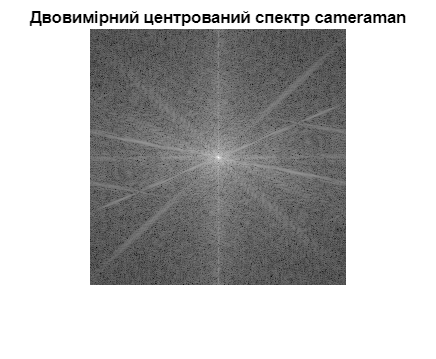

% 3. Привів нульову частоту в спектрі до центру вікна відображення
Fc1= fftshift(F1);
Fc2= fftshift(F2);
SFc1 = abs(Fc1);
SFc2 = abs(Fc2);
S1log = log(1 + SFc1);
S2log = log(1 + SFc2);
figure, imshow(S1log, []), title('Двовимірний центрований спектр cameraman');

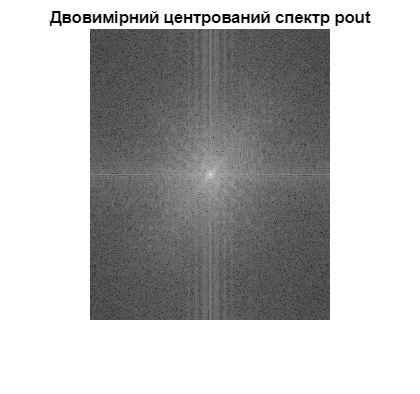

figure, imshow(S2log, []), title('Двовимірний центрований спектр pout');

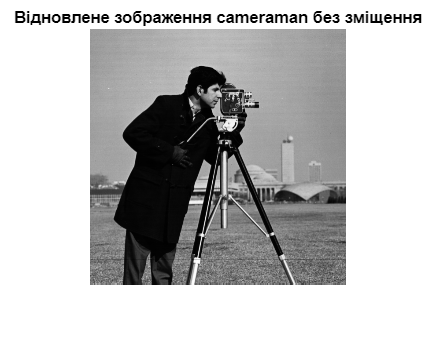

% 4. Відновив зображення за його спектром з нульовою частотою у верхньому лівому куті
If1 = ifft2(F1);
If2 = ifft2(F2);
figure, imshow(If1, []), title('Відновлене зображення cameraman без зміщення');

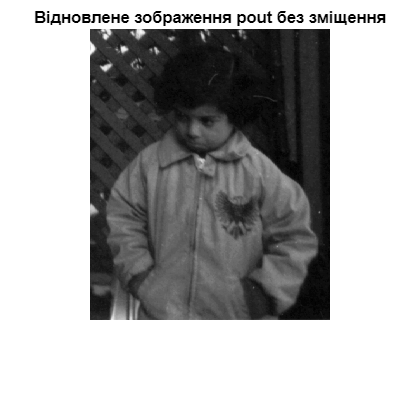

figure, imshow(If2, []), title('Відновлене зображення pout без зміщення');

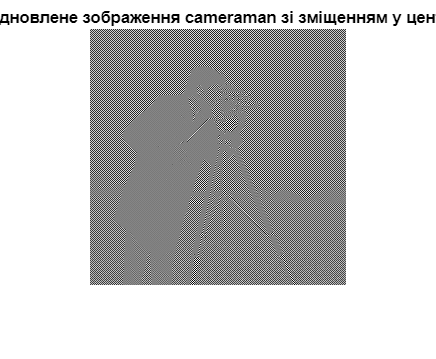

% 4.1. Відновив зображення за його спектром з нульовою частотою у центрі вікна
Ifc1 = ifft2(Fc1);
Ifc2 = ifft2(Fc2);
figure, imshow(Ifc1, []), title('Відновлене зображення cameraman зі зміщенням у центр');

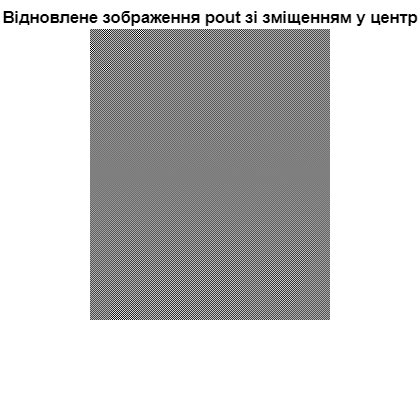

figure, imshow(Ifc2, []), title('Відновлене зображення pout зі зміщенням у центр');

% Пояснення до 4. ifft2 очікує вхідний спектр у стандартному форматі (нульова частота у верхньому лівому куті). 
% Тому перед застосуванням ifft2 треба зробити ifftshift, якщо спектр був зміщений. Без ifftshift результат буде спотворений, що бачимо у результаті

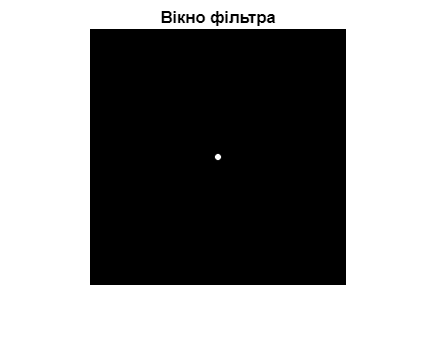

% 5. Задав двовимірний фільтр та відобразив вигляд вікна цього фільтра
sigma = 1;
h = fspecial('gaussian', [256 256], sigma);
figure, imshow(250*h), title('Вікно фільтра');

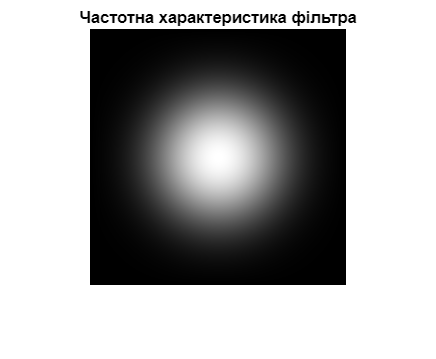

% 6. Визначив вигляд частотної характеристики даного фільтра.
H = fft2(h);
SH = abs(H);
Shc = fftshift(SH);
Shlog=log(1+Shc);
figure, imshow(Shlog, []), title('Частотна характеристика фільтра');

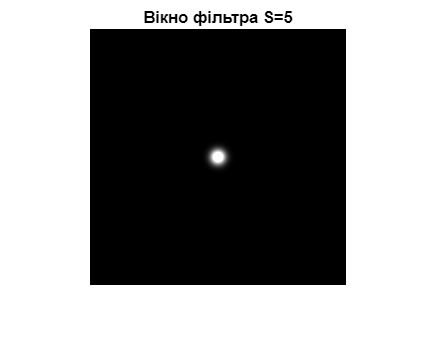

% 7. Змінив параметр sigma фільтра, і повторіть п.п. 5,6.
sigma = 5;
h = fspecial('gaussian', [256 256], sigma);
figure, imshow(250*h), title('Вікно фільтра S=5');

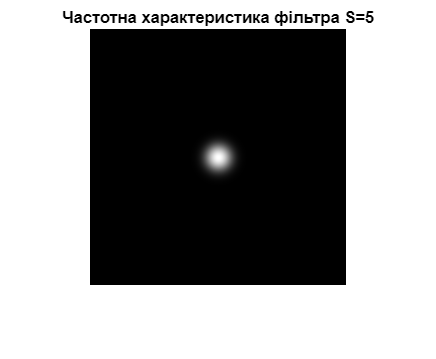

H = fft2(h);
SH = abs(H);
Shc = fftshift(SH);
Shlog = log(1+Shc);
figure, imshow(Shlog, []), title('Частотна характеристика фільтра S=5');

% Поянення до 7. Зі збільшенням sigma фільтр у просторі стає ширшим (розмитішим), а його частотна характеристика – вужчою, тобто пропускає менше високих частот. 
% Це призводить до сильнішого згладжування зображення.

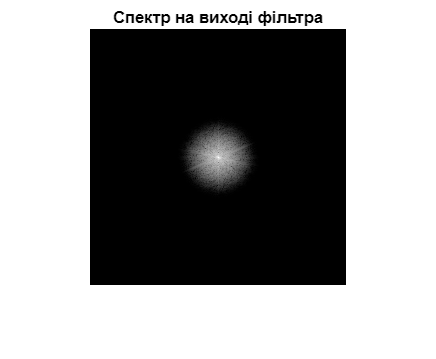

% 8. Виконав фільтрацію зображення у частотній області з використанням фільтрів згідно п.п. 5, 6, 7.
IF=F1.*H;
SIF=abs(IF);
Sifc= fftshift(SIF);
Sifclog=log(1+Sifc);
figure, imshow(Sifclog, [ ]), title('Спектр на виході фільтра');

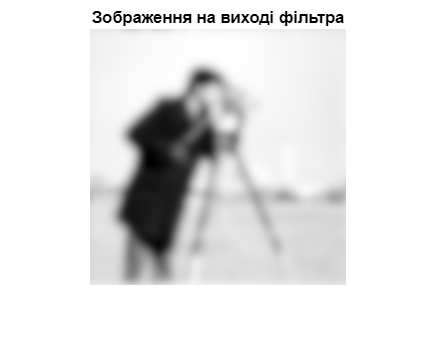

FI = ifft2(IF);
Fiabs=abs(FI);
Fiabsc= fftshift(Fiabs);
Filog=log(1+Fiabsc);
figure, imshow(Filog, []), title('Зображення на виході фільтра');

% Пояснення до 8. Чим більший показник sigma, тим сильніше фільтр прибирає високочастотну інформацію, і зображення виглядає м’якшим.

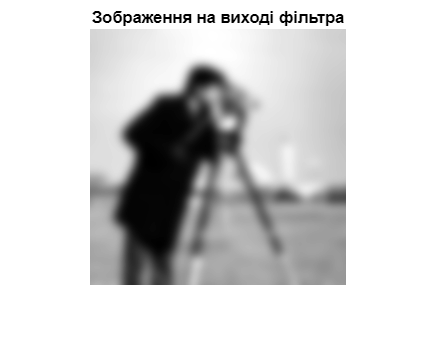

% 9. Виконав фільтрацію зображення в області просторових змінних.
F1_f = imfilter(a, h, 'replicate');
figure, imshow(F1_f, []), title('Зображення на виході фільтра');

% Пояснення до 9. Результати дуже схожі, бо обидва методи реалізують згортку з тим самим ядром. Фільтрація через imfilter (просторова область) 
% та через частотну область дає практично однаковий результат